# Laboratorio 3 - Modelo diferencial de primer orden

#### Grupo 8

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

Nuestro robot: Fanuc R-2000iC/125L

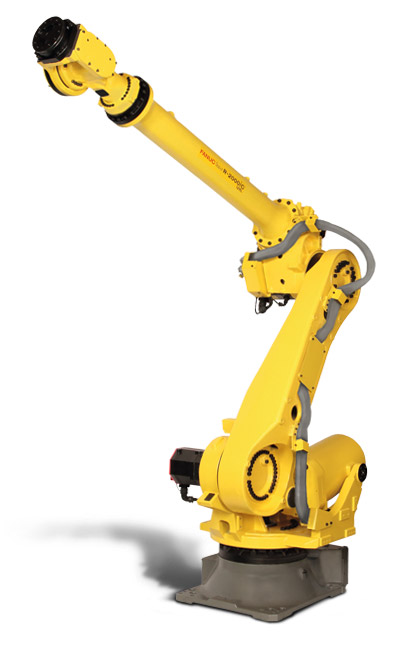

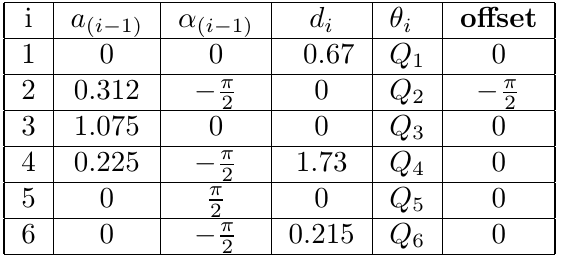

- Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numéricos, NO simbólicos) en función de los ángulos de articulación. 

La de arriba es la tabla de DH mod, para esta lab utilizaremos la DH estándar:

L(1) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0.67, 'offset',0,  ...
    'standard', 'qlim',[-pi pi]);

Unable to perform assignment because value of type 'Link' is not convertible to 'double'.

Caused by:
    Error using double
    Conversion to double from Link is not possible.

L(2) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',-pi/2,...
    'standard', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',pi/2, 'a', 0,    'd',1.73, 'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha',-pi/2,'a', 0,    'd',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',0,    'a', 0,    'd',0.215,'offset',0, ...
    'standard', 'qlim',[-pi pi]);

Robot = SerialLink(L,'name','R_{Fanuc}')

%Posición de las articulaciones del robot
q = [0 pi/2 0 -pi/2 0 0];

A_0_1 = L(1).A(q(1))
A_1_2 = L(2).A(q(2))
A_2_3 = L(3).A(q(3))
A_3_4 = L(4).A(q(4))
A_4_5 = L(5).A(q(5))
A_5_6 = L(6).A(q(6))

%Valores absolutos de 1 a 6
T_0_1 = A_0_1 * eye(4)
T_0_2 = A_0_1 * A_1_2 * eye(4)
T_0_3 = A_0_1 * A_1_2 * A_2_3 * eye(4)
T_0_4 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * eye(4)
T_0_5 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * eye(4)
T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 * eye(4)

%Las Z
Z_0 = [0; 0; 1]
Z_1 = [T_0_1(1,3); T_0_1(2,3); T_0_1(3,3)]
Z_2 = [T_0_2(1,3); T_0_2(2,3); T_0_2(3,3)]
Z_3 = [T_0_3(1,3); T_0_3(2,3); T_0_3(3,3)]
Z_4 = [T_0_4(1,3); T_0_4(2,3); T_0_4(3,3)]
Z_5 = [T_0_5(1,3); T_0_5(2,3); T_0_5(3,3)]

%Posiciones absolutas de los sistemas de referencia
T_0 = [0; 0; 0]
T_1 = [T_0_1(1,4); T_0_1(2,4); T_0_1(3,4)]
T_2 = [T_0_2(1,4); T_0_2(2,4); T_0_2(3,4)]
T_3 = [T_0_3(1,4); T_0_3(2,4); T_0_3(3,4)]
T_4 = [T_0_4(1,4); T_0_4(2,4); T_0_4(3,4)]
T_5 = [T_0_5(1,4); T_0_5(2,4); T_0_5(3,4)]
T_6 = [T_0_6(1,4); T_0_6(2,4); T_0_6(3,4)]

%Jacobiano
J = [cross(Z_0,(T_6-T_0)) cross(Z_1,(T_6-T_1)) cross(Z_2,(T_6-T_2))...
    cross(Z_3,(T_6-T_3)) cross(Z_4,(T_6-T_4)) cross(Z_5,(T_6-T_5));
    Z_0 Z_1 Z_2 Z_3 Z_4 Z_5]

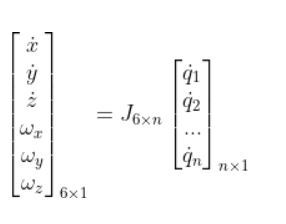

Ya se obtuvo el Jacobiano, ahora toca obtener el inverso.

Ahora para el punto 2. Para una postura de su elección dentro del espacio diestro del robot obtenga las velocidades de articulación para:

Como nuestro Jacobiano es cuadrado simplemente se encuentra el inverso del jacobiano de manera tradicional.

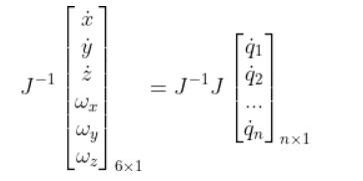

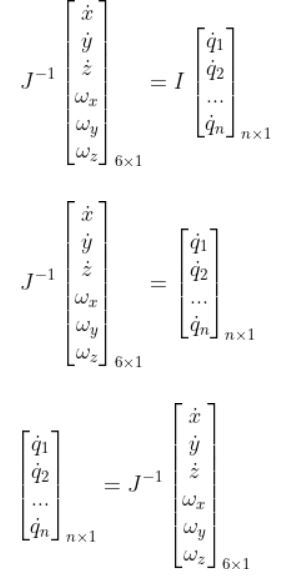

Jinv = pinv(J)

Para obtener la respuesta con los valores propuestos luego hacemos:

V_H = [100;200;50]
w_H = [5;10;-5]
vector = [V_H;w_H]
q_punto = Jinv*vector

Ubique la ruta seleccionada con la orientaci´on indicada dentro del espacio diestro del robot

horizontal = 3.1;
L = 0.4*horizontal;

r = 0.3*L;
n = 15;

t1 = [linspace(0,L-r,n)' zeros(n,2)];
theta = linspace(-pi/2,pi/2, n);
cx = (L-r);
cy = r;
cz = 0;

t2 = [cx+r*cos(theta)' cy+r*sin(theta)' cz+0.*theta'];
t3 = [t2(end,:);linspace(L-r,0,n)' 2*r.*ones(n,1) zeros(n,1)];
t4 = [t3(end,:);zeros(n,1) linspace(2*r,0,n)' zeros(n,1)];

ruta = [t1; t2; t3; t4];

clf
R0_t = rotx(45,'deg');
p0_t = [0 0.4 0.4];
ruta_ = 0.*ruta;
for i=1:length(ruta(:,1))
    ruta_(i,:) = R0_t*ruta(i,:)'+p0_t';
end

figure (1)
plot3(ruta_(:,1),ruta_(:,2),ruta_(:,3),'-bo')

Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articulación al recorrer la ruta.

Para esto se crea el robot con el RST

robot = rigidBodyTree;
body1 = rigidBody('body1'); 
body2 = rigidBody('body2'); 
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
bodyEndEffector=rigidBody('endeffector');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');
%body1
tform1 = transl(0, 0, 0.67);
setFixedTransform(jnt1,tform1); 
body1.Joint = jnt1;
addBody(robot,body1,'base')

%body2
tform2 = transl(0.312, 0, 0)*trotx(-pi/2)*trotz(-pi/2);
setFixedTransform(jnt2,tform2);
%setFixedTransform(jnt2,dhparams(2,:),'dh'); 
body2.Joint = jnt2;
addBody(robot,body2,'body1')

%body3
tform3 = transl(1.075, 0, 0);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2')

%body4
tform4 = transl(0.225, 1.73, 0)*trotx(-pi/2);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3')

%body5
tform5 = transl(0, 0, 0)*trotx(pi/2);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4')

%body6
tform6 = transl(0, 0.215, 0)*trotx(-pi/2);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5')

%endEffector
tform7 = trvec2tform([0 0 0]);
setFixedTransform(bodyEndEffector.Joint,tform7);
addBody(robot,bodyEndEffector,'body6')

Ahora la cinemática inversa

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = homeConfiguration(robot);
robot.BodyNames

viapoints = length(ruta(:,1));
conf_ruta = zeros(viapoints,6);
for i=1:viapoints
    tic
    if i>1
        initialguess = configSoln;
    end
    p0_t = ruta_(i,:);
    R0_t = rotx(-135,'deg');
    MTHpose = [R0_t p0_t'; 0 0 0 1];
    [configSoln,solnInfo] = ik('endeffector',MTHpose,weights,initialguess);
    conf_ruta(i,:) = [configSoln(1).JointPosition configSoln(2).JointPosition configSoln(3).JointPosition ...
        configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
    disp(strcat(num2str(i),"/",num2str(viapoints)))
    toc
end

figure (2)
plot(conf_ruta(:,1)*180/pi)
hold on
plot(conf_ruta(:,2)*180/pi)
hold on
plot(conf_ruta(:,3)*180/pi)
hold on
plot(conf_ruta(:,4)*180/pi)
hold on
plot(conf_ruta(:,5)*180/pi)
hold on
plot(conf_ruta(:,6)*180/pi)
hold off

Para la animación del robot dibujando la trayectoria en el plano de trabajo:

fps=60;r=rateControl(fps);
show(robot,conf_ruta(1,:))
ax=gca;
hold on
plot3(ax,ruta_(:,1),ruta_(:,2),ruta_(:,3),'-bo');
hold on
while true
    for i=1:waypoints
        show(robot,conf_ruta(i,:),'PreservePlot',false);
        drawnow
        waitfor(r);
    end
end 

Para la velocidad fija en la trayectoria (500mm/s):

Jacobianos = cell(1,waypoints);
for i=1:waypoints
    Jacobianos{i} = geometricJacobian(robot,conf_ruta(i,:),'tool0');
end

tiempos = zeros(61,1);
distancia_tot = 0;
distancias = zeros(61,3); 
velocidad = 0.5;
for j=1:waypoints-1
    norma = norm(ruta_(j+1,:)-ruta_(j,:)); 
    distancia_tot = distancia_tot + norma;
    if norma ~= 0
        distancias(j,:) = (ruta_(j+1,:)-ruta_(j,:));
        tiempos(j) = norma/velocidad;
    else
        distancias(j,:) = [0 0 0];
    end
end

Para la velocidad lineal instantánea:

v = zeros(61,3);
for k=1:waypoints-1
    if(tiempos(k) ~= 0)
        v(k,:) = (distancias(k)/tiempos(k));
    else
        v(k,:) = [0 0 0];
    end
end
v = [[0 0 0]; v];
w = zeros(62,3);
vw = [v, w];
q_punto = zeros(6,62);

for i=1:waypoints
    q_punto(:,i) = inv(Jacobianos{i})*vw(i,:)';
end

t = zeros(62,1);
for i = 2 : waypoints
    t(i) = t(i-1) + tiempos(i-1);
end 

Graficando:

clf
for i=1:6
    plot(t,q_punto(i,:), 'DisplayName',['q dot_',num2str(i)])
    hold on
end
legend('Location',"southeast")
grid on
hold off
title('Velocidad de articulaciones')
xlim([0.00 3.00])
ylim([-4.00 4.00])
xlabel('Tiempo (s)')
ylabel('Velocidad articular (Rad/s)')